# EFMouse: 1xLumbar montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 1xLumbar montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver getDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '1xLumbar';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/1xLumbar'; % Results and the object (1xLumbar.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o

Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

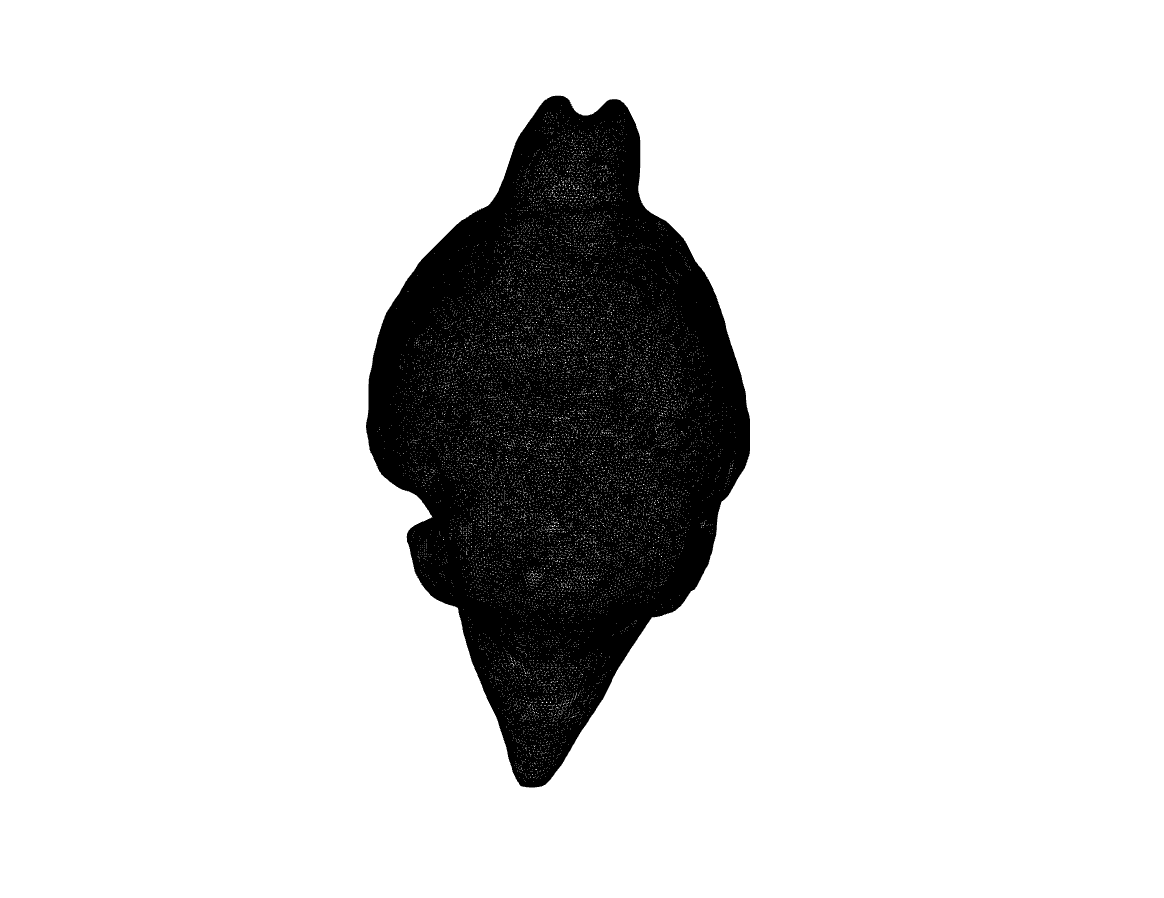

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 1 x Lumbar stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin). We simulate a circular stimulation anode on top of the visual areas, and a rectangular return cathode in the lumbar.

o.addElectrode(tag = "Anode",current = 0.2,type="surface",shape="circle",center= [-3.5,27.5,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lumbar",current = -0.2,type="surface",shape="rectangle",center=[-1,-12,10],length=15,width=15,thickness=1);

To update the model with the electrodes, we run the pipeline to Stage.MESH. 

We can set show=false, and then plot using plotMesh() showing skin tissue to visualize the electrode in the lumbar. We also adjust the ylim dimensions to visualize the whole body.

o.run(targetStage=Stage.MESH,show=false)

Compute stage MESH
EF Mouse Model (label: 1xLumbar) in directory /Users/rubensanchez/desktop/efmouse_sim/1xLumbar (stage=INIT).
-Meshing 2 electrodes-
Closest skin node is 0.4 away from the Anode electrode target position.
Closest skin node is 0.5 away from the Lumbar electrode target position.
Stage MESH complete - 97.4389 seconds 


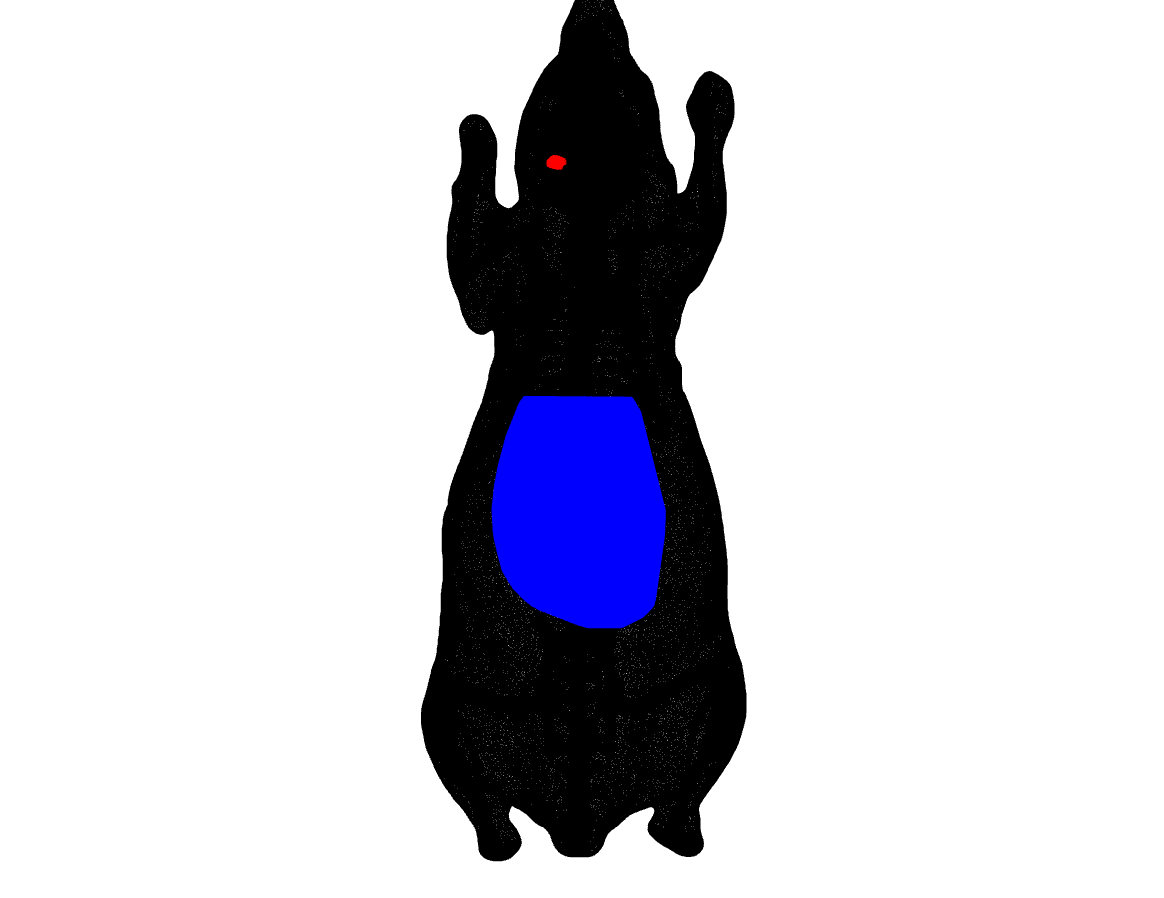

plotMesh(o,tissue="skin")
ylim([-37 37])

This mesh shows the electrodes in red (anode) and blue (cathode).

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in 4*x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...02-Jun-2025 18:12:24
----saveMesh elapsed time: 30.4882 seconds

----Starting savePro...02-Jun-2025 18:12:55
----savePro elapsed time: 0.0716 seconds

Stage EXPORT complete - 21.9268 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 02-Jun-2025 18:12:55 
 ID: 1xLumbar 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/1xLumbar 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anode = Region[6];
Lumbar = Region[7];
boundaryAnode = Region[8];
boundaryLumbar = Region[9];
DomainC = Region[{gray,csf,bone,skin,eye,Anode,Lumbar}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anode,Lumbar,boundaryAnode,boundaryLumbar}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anode] = 0.3;
sigma[Lumbar] = 0.3;
du_dnAnode[] = 110.774083;
du_dnLumbar[] = -0.524215;
}

Jacobian {
  { Name Vol ;
    Case {
      { Region All ; Jacobian Vol ; }
    }
  }
  { Name Sur ;
    Case {
      { Region All ; Jacobian Sur ; }
    }
  }
}


Integration {
  { Name GradGrad ;
    Case { {Type Gauss ;
            Case { { GeoElement Triangle    ; NumberOfPoints  3 ; }
                   { GeoEl

This file can be opened in the getDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/EFMouse/lib/getdp-3.2.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Mon Jun  2 18:17:29 2025, Wall = 0.0976682s, CPU = 0.06858s, Mem = 5.40234Mb)
Info    : Initializing Gmsh
□□Error   : Unknown number option 'General.NativeFileChooser'□
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                            

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...02-Jun-2025 18:58:05


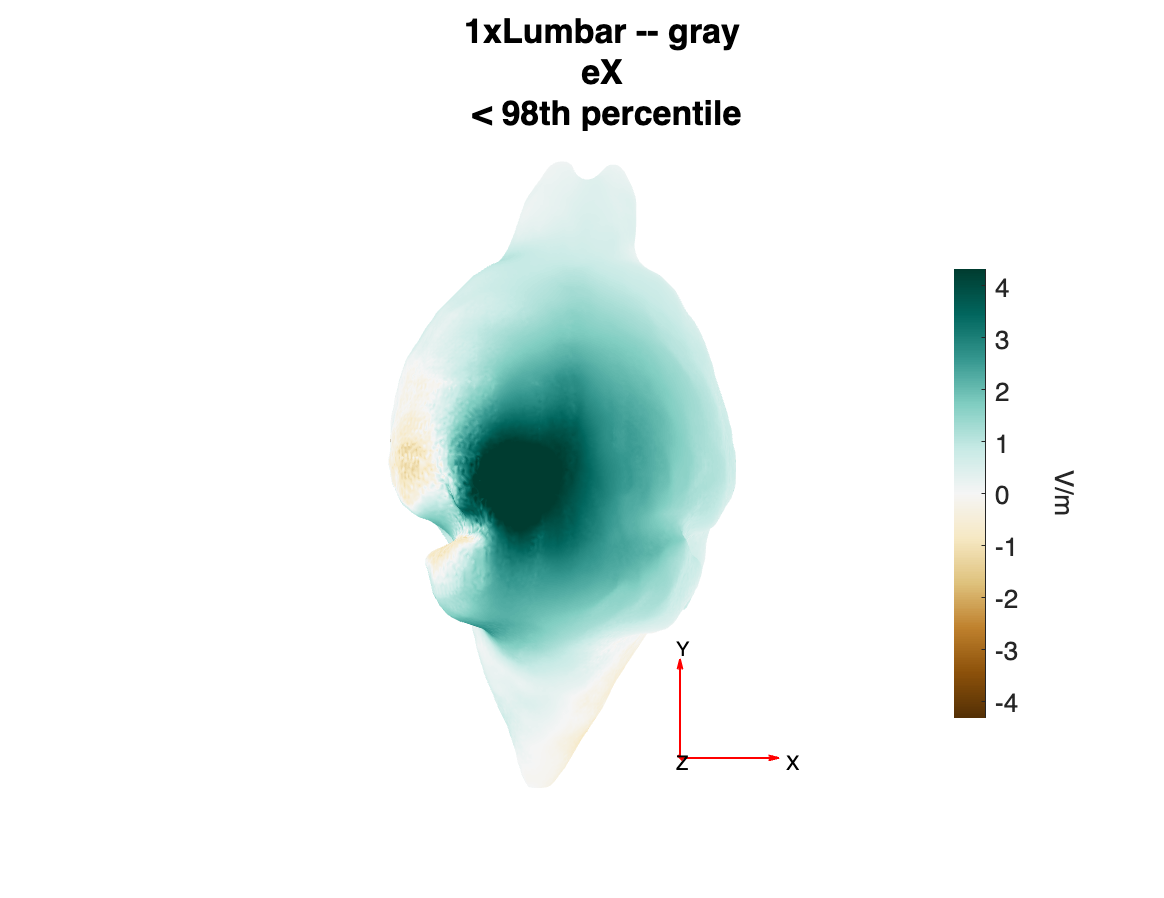

----plotEf elapsed time: 4.0178 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...02-Jun-2025 18:58:09


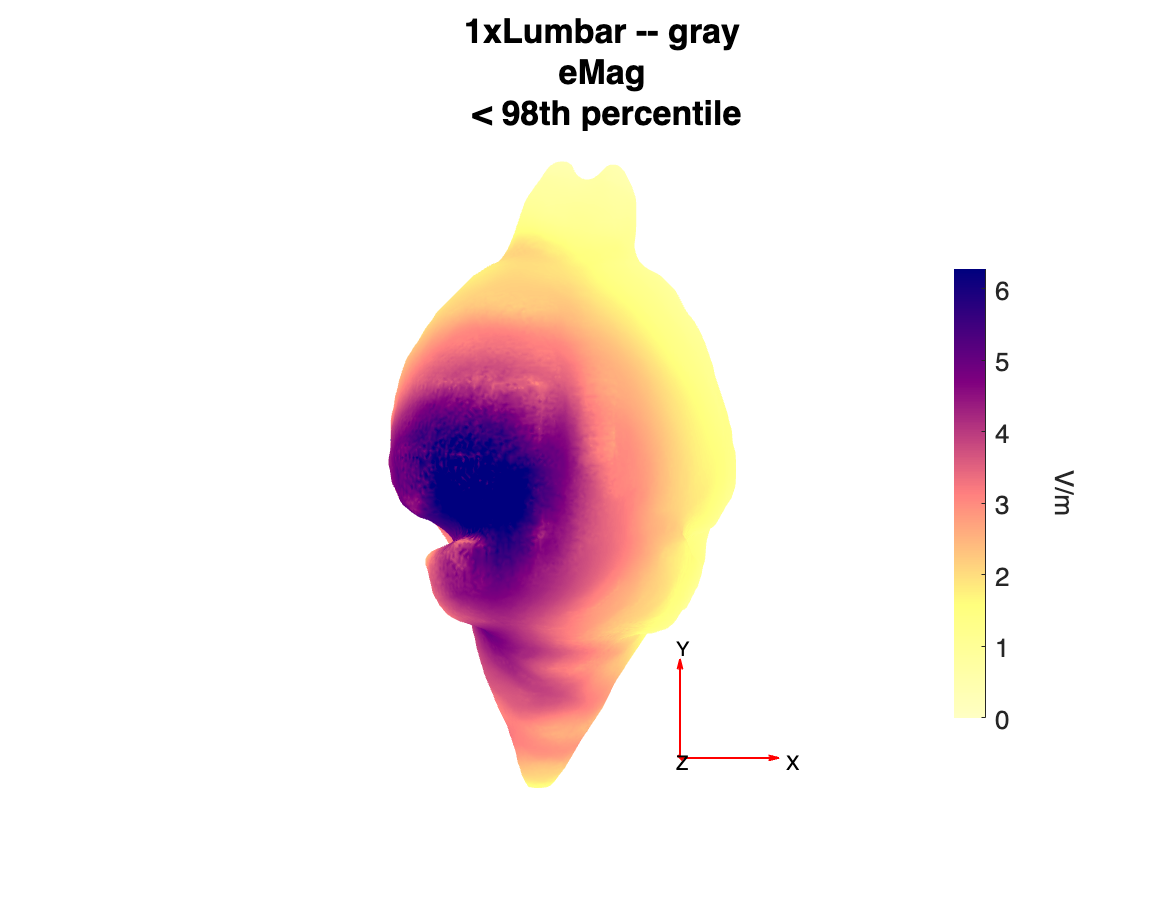

----plotEf elapsed time: 2.2772 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol.

See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o,["skin" "gray"])

----Starting analyzeTissue...02-Jun-2025 18:58:32
Electric field summary statistics for skin tissue
             mean       median       std         min         max  
            _______    _________    ______    __________    ______

    eX      0.28675    0.0031563    3.2945       -110.54    175.73
    eY      -1.0622     -0.55873    2.6952       -155.08    136.56
    eZ      -0.5017      0.02422    5.9647       -309.89    42.628
    eMag     1.9837        1.041     7.157    9.6118e-07    346.72

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.5874, for ef_norm_mean: (0.044 -0.562 0.165)

Electric field summary statistics for gray tissue
             mean       median       std        min

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2014), for definitions of relative focality and homogeneity.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  %Left/right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Z
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.

----Starting analyzeRoi...02-Jun-2025 18:59:03
Electric field summary statistics for a box roi in gray
             mean       median       std        min        max  
            _______    ________    _______    _______    _______

    eX       1.2422      1.3712    0.92365    -1.5353     3.2231
    eY      -1.0341    -0.96759     1.0952    -4.2428     1.3652
    eZ      -5.1872     -4.9696    0.82864    -7.9745    -3.2652
    eMag     5.6217      5.3833    0.80884     4.3393     8.3397

[Relative focality ranges from 0 to 1]
Relative focality = 0.9818, with 160508 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9658, for ef_norm_mean: (0.216 -0.186 -0.923)


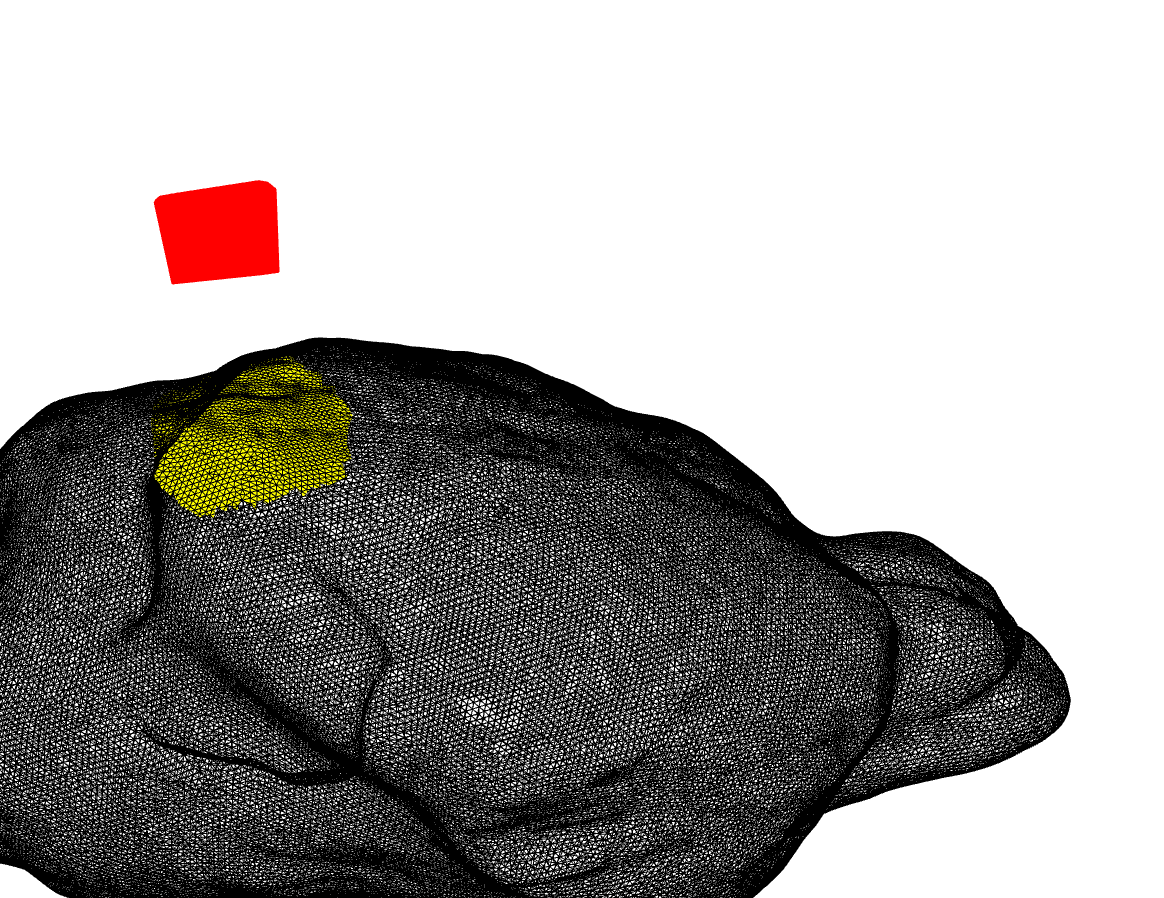

% Rotate and zoom to view the (yellow) box ROI underneath the return electrode
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=75);

----Starting analyzeRoi...02-Jun-2025 18:59:10
Electric field summary statistics for a box roi in gray
              mean       median       std        min        max   
            ________    ________    _______    _______    ________

    eX         1.282      1.2895     0.2134    0.74629      1.8291
    eY      -0.70015    -0.67334    0.18862    -1.2473    -0.37734
    eZ       -1.0859     -1.0879    0.12783    -1.3629    -0.76982
    eMag      1.8329      1.8273    0.22578     1.3278      2.4107

[Relative focality ranges from 0 to 1]
Relative focality = 0.3964, with 160925 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9931, for ef_norm_mean: (0.698 -0.382 -0.59

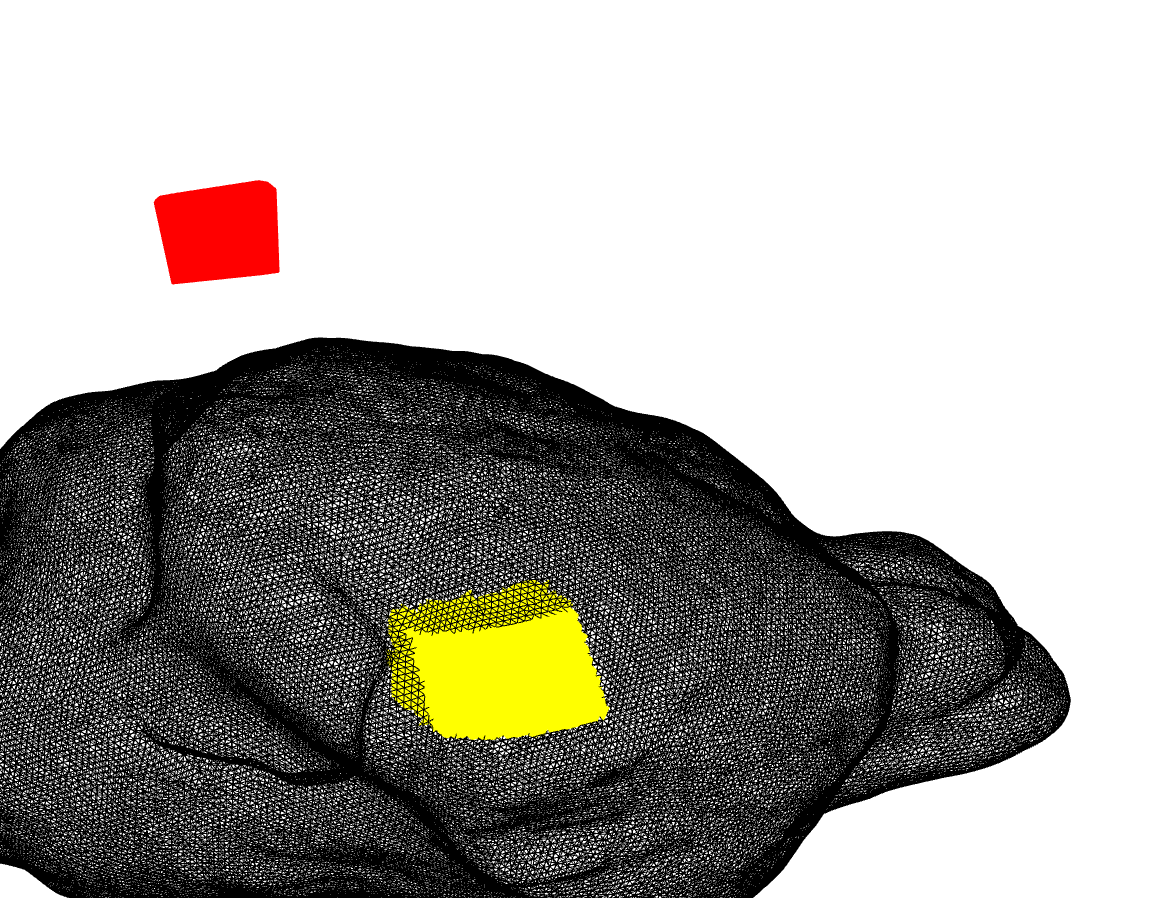

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...02-Jun-2025 19:00:04
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1xLumbar/1xLumbar_efZ.nii.gz created
----computeVoxelSpace elapsed time: 24.4845 seconds
Stage ATLAS complete - 46.9019 seconds 


### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...02-Jun-2025 19:47:06
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median      std         min        max  
            _______    _______    ______    _________    ______

    eX       3.2881     3.7586    1.6303      -0.7873    6.2618
    eY      -1.2745    -1.0903    1.5853      -5.1701    2.4158
    eZ      -5.7606    -5.9788    1.8961      -9.7006         0
    eMag     7.0702     7.5057    2.1122    0.0027404    10.824

[Relative focality ranges from 0 to 1]
Relative focality = 0.9986, with 92410 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9499, for ef_norm_mean: (0.460 -0.183 -0.811)
----analyzeAtla

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...02-Jun-2025 19:47:07
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean       median       std         min         max   
            ________    ________    _______    _________    ________

    eX        1.6462      1.7634    0.74693    0.0020763      2.8952
    eY      -0.87165    -0.95037    0.42619      -1.7359    0.016212
    eZ       -1.1141     -1.1812    0.51421       -1.976           0
    eMag      2.1982      2.3833    0.94074    0.0026452       3.569

[Relative focality ranges from 0 to 1]
Relative focality = 0.6234, with 92457 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9870, for ef_norm_mean: (0.745

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/1xLumbar',ID='1xLumbar')